clc
clear
y21=523;    
y22=587; 
y23=659;
y24=698;
y25=784;
y26=880;
y27=988;
%形成一段音乐 小星星乐谱
f1 = [y21,y21,y25,y25,y26,y26,y25,y24,y24,y23,y23,y22,y22,y21,y25,y25,y24,y24,y23,y23,y22,y25,y25,y24,y24,y23,y23,y22,y21,y21,y25,y25,y26,y26,y25,y24,y24,y23,y23,y22,y22,y21];
Fs = 8000; %采样频率
tp1 = 0.5.*ones(1,length(f1)); %每个音符持续时间，单位为s
am = randi([1,5],1,42);  %随机数产生弹奏钢琴时的强度
x1 = 0; %将音乐初始化为0，后面逐渐更新
for i = 1:length(f1)
    f = f1(i);
    tp = tp1(i);
    t = 0:1/Fs:tp-1/Fs;
    x = am(i)*sin(2*pi*f*t); %读取每个音符及持续时间
    x1 = [x1 x];
end
sound(x1,Fs)
% 设置文件名称
filename = 'wohewodezuguo.wav';
% 保存音乐至文件
audiowrite(filename,x1,Fs)

%绘制时域波形
t = 0:1/Fs:sum(tp1);
figure,subplot 211, plot(t,x1);
title('时域波形');ylabel('幅值'); xlabel('时间/s');
%时域转换到频域并绘图
% x1fft=dft(x1,Fs)
x1fft = fft(x1);
freq = ((1:length(x1fft)/2)-1)*Fs/length(x1fft);
subplot 212, plot(abs(x1fft(1:length(x1fft)/2)));

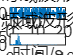

xlabel('频率/Hz');
title('频域波形');
ylabel('DFT幅值'); 